# trf_mkFigure7

Descriptions:

## Load data

whichData = 'fmri1ecc'; 
dataLoc      = fullfile(fileparts(temporalfMRIRootPath), 'files');

[a, b]    = loadfiles(dataLoc, whichData);
data      = a.(whichData).data;
roiNms    = a.(whichData).nm;
stn       = b.(whichData).stn;

nRois     = length(roiNms);

## compute lower and higher eccentricity model fit (for Figure 7A), and summary metrics (for figure 7B)

mprd = {}; metric = []; metric = [stn.derivedParam.r_double; stn.derivedParam.t_isi];

% compute mean and std of data
for k1 = 1 : 2
    mdata{k1} = squeeze(mean(data(k1, :, :, :), 3));
    sdata{k1} = squeeze(std(data(k1, :, :, :), [], 3));
end

for k = 1 : length(roiNms)
    idx{1} = (k - 1) * 100 + 1 : k * 100;
    idx{2} = idx{1} + 900;
    
    % compute mean and std model fit
    for k1 = 1 : 2
        mprd{k1}(k, :) = mean(stn.prd(idx{k1}, :));
        sprd{k1}(k, :) = std(stn.prd(idx{k1}, :));
    end
    
    % compute summary metrics
    for k1 = 1 : 2
        mmetrics{k1}(k, :)    = median(metric(:, idx{k1}), 2);
        smetrics{k1}(k, :, :) = prctile(metric(:, idx{k1}), [25, 75], 2);
    end
end

## Plot Figure 7

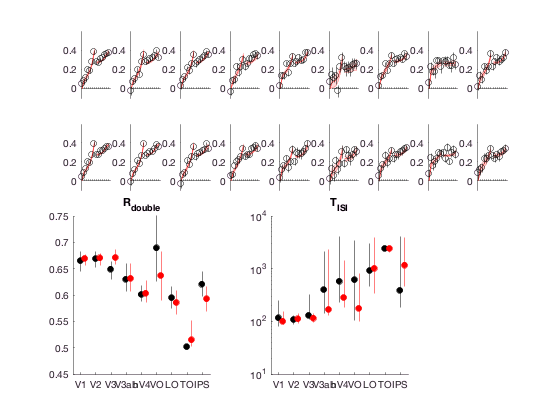

figure (7), clf

order = [13, 1 : 6, 5, 7 : 12];

for k = 1 : nRois
    for k1 = 1 : 2
        subplot(4, nRois, (k1 - 1) * nRois +k)
        % plot model fit
        shadedErrorBar(1 : 7, mprd{k1}(k, order(1 : 7)), sprd{k1}(k, order(1 : 7)), 'r-'), hold on
        shadedErrorBar(8 : 14, mprd{k1}(k, order(8 : 14)), sprd{k1}(k, order(8 : 14)), 'r-')
        % plot data
        plot(mdata{k1}(k, order), 'ko'),
        for k2 = 1 : length(order)
           plot([k2, k2], [mdata{k1}(k, order(k2)) - sdata{k1}(k, order(k2)), mdata{k1}(k, order(k2)) + sdata{k1}(k, order(k2))], 'k-') 
        end
        box off, xlim([0.5, length(order) + 0.5]), set(gca, 'xtick', 1 : length(order), 'xticklabel', '', 'xaxislocation', 'origin'),
        ylim([-0.1, 0.6])
    end
end

% plot summary parameters
loc = {[19, 20, 21, 28, 29, 30]; [23, 24, 25, 32, 33, 34]};

subplot(4, nRois, loc{1})
plot(1 : nRois, mmetrics{1}(:, 1), 'ko', 'markerfacecolor', 'k'), hold on
plot(1.3 : nRois+0.3, mmetrics{2}(:, 1), 'ro', 'markerfacecolor', 'r'), box off
for k = 1 : nRois
    plot([k, k], squeeze(smetrics{1}(k, 1, :)), 'k-')
    plot([k+0.3, k+0.3], squeeze(smetrics{2}(k, 1, :)), 'r-')
end
xlim([0.5, nRois + 0.5]), set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms)
title('R_{double}'),  ylim([0.45, 0.75]),

subplot(4, nRois, loc{2})
semilogy(1 : nRois, mmetrics{1}(:, 2), 'ko', 'markerfacecolor', 'k'), hold on
semilogy(1.3 : nRois+0.3, mmetrics{2}(:, 2), 'ro', 'markerfacecolor', 'r'), box off
for k = 1 : nRois
    plot([k, k], squeeze(smetrics{1}(k, 2, :)), 'k-')
    plot([k+0.3, k+0.3], squeeze(smetrics{2}(k, 2, :)), 'r-')
end
xlim([0.5, nRois + 0.5]), set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), title('T_{ISI}')